# Optimización unidimensional usando aproximación usando Rectas Inexactas en MATLAB

**Alumno:** Pablo Ruiz Molina

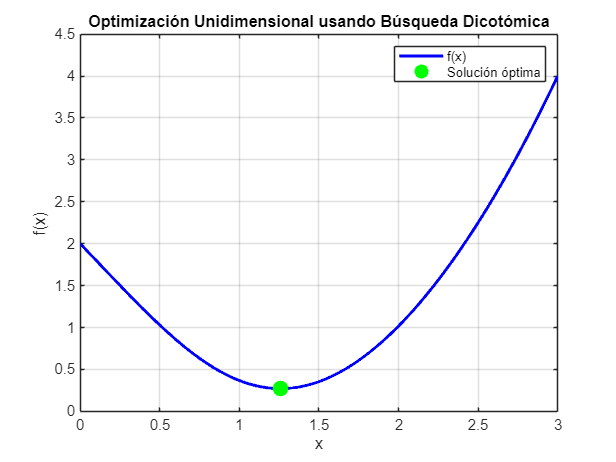

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda
delta = 1e-6;  % Tolerancia (delta)
alpha = 10^-4; beta = 10^-1; % Consideracioens inciales
max_iter = 100;  % Número máximo de iteraciones

% Obtener la solución óptima final
[f_opt, x_opt, iter] = rein(f, a, b, alpha, beta, delta, max_iter);


% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
legend('f(x)');
hold on;
% Marcar la solución óptima en el gráfico
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;
hold off;

% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720



## Anexo

function [f_opt, x_opt, iter] = newton(f, a, b, delta, max_iter)
    % Método de Newton para encontrar un mínimo local en una función unimodal
    % Entradas:
    %   f        - Función objetivo (debe ser diferenciable en [a, b])
    %   a, b     - Extremos iniciales del intervalo [a, b]
    %   delta    - Tolerancia para la convergencia
    %   max_iter - Número máximo de iteraciones permitidas
    %
    % Salidas:
    %   f_opt:   - valor de la función dónde se alcanza el óptimo 
    %   x_opt    - Aproximación del punto donde f'(x) = 0 (mínimo o máximo)
    %   iter     - Número de iteraciones realizadas
    
    % Paso 1: cálculo del punto inicial.
    xn = (a + b)/2;
    
    % Paso 2: derivar (primera y segunda) la función numéricamente
    syms x
    df = matlabFunction(diff(f, x));
    df2 = matlabFunction(diff(f, x, 2));
    
    % Paso 3: proceso iterativo de Newton
    iter = 0;
    error1 = 1;
    error2 = 1;
    while error1 > delta && error2 > delta && iter < max_iter
        iter = iter + 1;
        
        % Paso 4: aplico Newton para calcular el nuevo punto.
        xn_1 = xn - df(xn)/df2(xn);

        % Paso 5: calculo errores
        error1 = abs(df(xn));
        error2 = abs(xn_1 - xn);

        % Paso 6: actualizo xn
        xn = xn_1;
    end

    % Paso 7: Si no converge, devolver x_opt = 0;
    x_opt = xn;
    f_opt = f(x_opt);
end


function [f_opt, x_opt, iter] = rein(f, a, b, alpha, beta, delta, max_iter)
    % Método de las rectas inexactas con las condiciones de Armijo y Goldstein.
    %
    % Entradas:
    %   f        - Función objetivo (handle)
    %   a, b     - Extremos iniciales del intervalo [a, b]
    %   alpha    - Parámetro para las condiciones (0 < alpha < 0.5)
    %   beta     - Factor de reducción del paso (0 < beta < 1)
    %   delta      - Tolerancia para la convergencia
    %
    % Salidas:
    %   x_opt    - Punto aproximado donde se alcanza el mínimo
    %   iter     - Número de iteraciones realizadas

    syms x

    % Paso 1: cálculo del punto inicial.
    xk = (a + b)/2;
    
    % Paso 2: proceso iterativo de Newton
    h = 1/1000; % Tamañp de paso. -> Aproximar gradiente
    grad_lambda_d = 1; % Para no cumplir el criterio de parada
    iter = 0;
    while abs(grad_lambda_d) > delta && iter < max_iter
        iter = iter + 1;
        
        % Paso 3. cálculo de dirección de descenso
        grad = grad_lambda_d; % grad(f(xk)) (ya calculada en la iteración anterior)
        d = -grad;


        % Paso 4. Búsqueda lineal para encontrar tamaño de paso lambda
        % 4a. Inicializar lambda
        lambda = 1;

        % 4b. Evalúo la función en xk y xk + lambda_d
        fxk = f(xk);
        fxk_lambda_d = f(xk + lambda*d);
        
        % 4c. Cálculo de grad(f(xk + lambda*d))
        grad_lambda_d = matlabFunction(diff(f(x + lambda*d), x));
        grad_lambda_d = grad_lambda_d(xk);

        % 4d. Mientras Armijo o Wolfe:
        while ((fxk_lambda_d > fxk + alpha*lambda*grad*d) || (beta*grad*d > grad_lambda_d*d))
            % Paso 5. Actualizo lambda
            lambda = 0.5*lambda;
            
            % Paso 6. Actualizo grad(f(xk + lambda*d))
            grad_lambda_d = matlabFunction(diff(f(x + lambda*d), x));
            grad_lambda_d = grad_lambda_d(xk);
            
            % Paso 7. Actualizo la evaluación de la función en lambda
            fxk_lambda_d = f(xk + lambda*d);

            % Prevenir bucles infinitos.
            if lambda < 0.00001
                break;
            end
        end 
        
        % Paso 8. Actualizo xk con el lambda obtenido
        xk = xk + lambda*d;

    end
    % Paso 9: Cálculo del mínimo
    x_opt = xk;
    f_opt = f(x_opt);
end